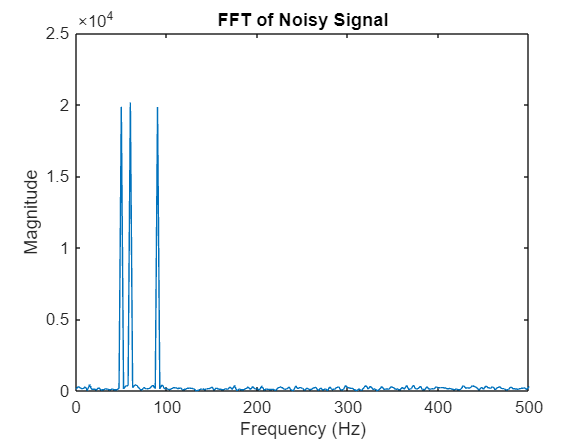

% Project 1: Communication Signal Visualizer 
% Build a MATLAB GUI that can: 
% • Generate signals  
% • Add noise  
% • Show FFT  
% • Show PSD  
% • Apply filters  
% Concepts used: Signals Noise FFT PSD Filters 

fs = 100000;                     % Sampling frequency
t = 0.1 : 1/fs : 0.5;             % Time vector

% Generate signals
sig1 = sin(2*pi*50*t);
sig2 = sin(2*pi*60*t);
sig3 = sin(2*pi*90*t);
signal = sig1 + sig2 + sig3;      % Combined signal

% Add noise
noise = randn(size(t));
noisy_signal = signal + noise;

% FFT
N = length(noisy_signal);         % Number of samples
Y = fft(noisy_signal);            % Compute FFT
f = (0:N-1)*(fs/N);               % Frequency axis

% Plot magnitude spectrum
figure;
plot(f, abs(Y));
xlim([0 500]);                    % Limit to 0–500 Hz for clarity
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('FFT of Noisy Signal');

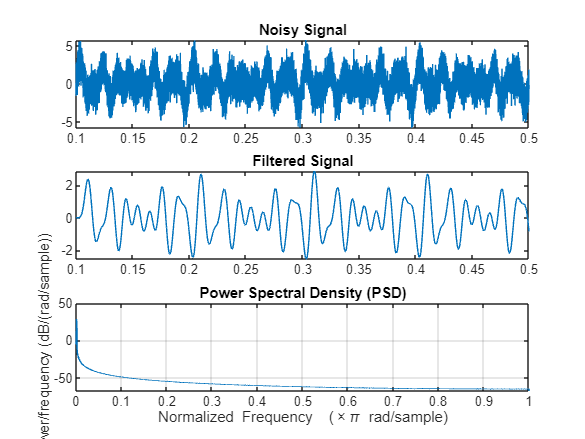



% Design Butterworth filter
[b, a] = butter(6, 100/(fs/2));   % 6th order low-pass filter
filtered_signal = filter(b ,a, noisy_signal);

% Plot signals
figure;
subplot(3,1,1);
plot(t, noisy_signal);
title('Noisy Signal');

subplot(3,1,2);
plot(t, filtered_signal);
title('Filtered Signal');

subplot(3,1,3);
pwelch(filtered_signal);
title('Power Spectral Density (PSD)');